Maximum channel capacity after applying Shannon's Law at existing conditions is 3829


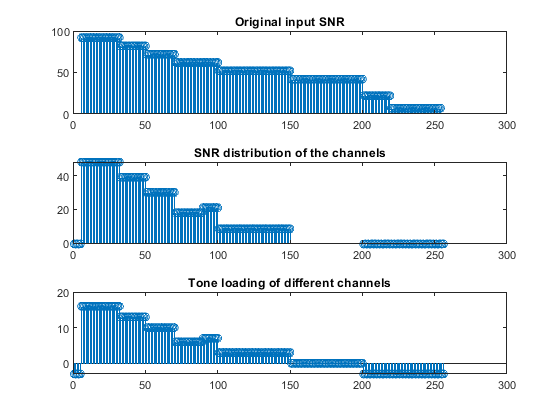

t=1:256; % Tone loading table not yet used.
snr=SPN_to_SNR_converter(); % Get the SNR table
b=adaptive_fine_gains(snr,1024); % Get the adaptive bit loading

b=[b.nbits_rounded] % Get only the number of rounded bits in the channel

b =     -3    -3    -3    -3    -3    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    13    13    13    13    13    13    13    13    13    13    13    13    13    13    13    13    13    13


[~,Nsc] = size(b); % Number of sub-carriers
sum(b)

ans = 1024

data = creverb1(Nsc); % PRBS
size(data)

ans =            1        1024


QAM_symbols = qam_mod(data,b,t) % QAM symbols

k = -2

k = -5

k = -8

k = -11

k = -14

Array indices must be positive integers or logical values.

Error in bit_extract (line 44)
            extracted_bits{ii} = (data(k : k + b_n(ii) - 1))'; % This is being used

Error in qam_mod (line 26)
        extracted_bits = bit_extract(data,b_n); % Extract bits onto the variable based on bit allocation table

bit_stream_rcvd = qam_demod(QAM_symbols,b); % Perform demod on the receiver end
data = data(1:sum(b)); % Get the BER
err = sum(bit_stream_rcvd ~= data)